## Modélisation de l'activité électrique du cerveau 

#### I. Système à 2 neurones

#### Q1 Exploration

On se propose ici de mettre en place un code avec curseurs pour représenter la variation des courbes s1, s2 selon la variatiation de différents paramètres

clear all;
close all;
clc;

% Définition des fonctions
Phi1 = @(x) max(0,x);
Phi2 = @(x, b) 1 ./ (1 + exp(-b*x));

function [t, s] = euler(W, B, s0, lambda, tspan, phi_choice, b_param)
    N = 1000;
    pas = tspan(2)/N;
    
    % Choisir la fonction selon phi_choice
    if phi_choice == 1
        Phi = @(x) max(0,x);
    else
        Phi = @(x) 1 ./ (1 + exp(-b_param*x));
    end
    
    f = @(t, s) -lambda * s + Phi(W * s + B); % equation
    
    t = zeros(N + 1, 1);
    s = zeros(N + 1, 2);
    
    t(1) = tspan(1);
    s(1, :) = s0;
    
    % Euler
    for i = 1:N
        f_i = f(t(i), s(i, :)');
        s(i+1, :) = s(i, :) + pas * f_i';
        t(i+1) = t(i) + pas;
    end
end

% Initialisation des paramètres
W = [1, 1; 1, 1];
B = [1; 1];
s0 = [1; 1];
lambda_val = 2;
tspan = [0 10];
phi_choice = 1; % 1 pour Phi1, 2 pour Phi2
b_param = 1; % Paramètre b pour Phi2

% Fonction de tracé
function tracer_graph(lambda_val, s_01, s_02, B1, B2, w11, w12, w21, w22, phi_choice, b_param)
    W = [w11, w12; w21, w22];
    B = [B1; B2];
    s0 = [s_01; s_02];
    tspan = [0 10];
    
    [t, s] = euler(W, B, s0, lambda_val, tspan, phi_choice, b_param);
    
    plot(t, s, 'LineWidth', 2);
    xlabel('Temps (t)', 'FontSize', 12);
    ylabel('États s_i(t)', 'FontSize', 12);
    grid on;
    legend('s_1(t)', 's_2(t)', 'Location', 'best', 'FontSize', 11);
    
    % Titre avec indication de la fonction choisie
    if phi_choice == 1
        titre = 'Modélisation avec Phi1: max(0,x)';
    else
        titre = sprintf('Modélisation avec Phi2: sigmoïde (b=%.1f)', b_param);
    end
    title(titre);
end

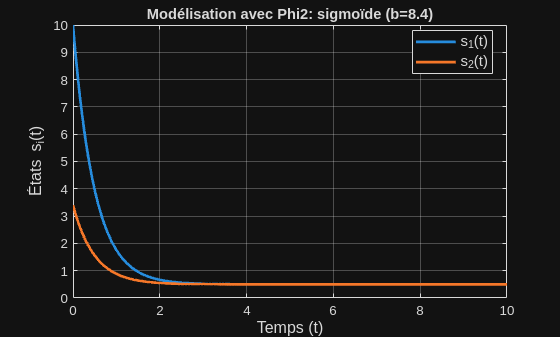

lambda_val =2;
s_01 =10;
s_02 =3.4;
B1 =1;
B2 =1;
w11 =1;
w12 =1;
w21 =1;
w22 =1;
b_param =8.4;
phi_choice = 2;
%% Tracé
tracer_graph(lambda_val, s_01, s_02, B1, B2, w11, w12, w21, w22, phi_choice, b_param);

#### Conclusion

Conclusion pertinente

####     II. Système à n neurones

#### Q2/ Exploration

%% Question 2 - Système à n neurones

clear all;
close all;
clc;

%% Définition du nombre de neurones
n = 5;

%% Fonctions

% Fonction d'activation selon phi_choice
function Phi = get_activation_function(phi_choice, beta)
    if phi_choice == 1
        % ReLU: max(0,x)
        Phi = @(x) max(0, x);
    else
        % Sigmoïde
        Phi = @(x) 1 ./ (1 + exp(-beta * x));
    end
end

% Méthode d'Euler
function [t, s] = euler2(W, B, s0, lambda, tspan, phi_choice, beta)
    n = length(s0);
    N = 1000;
    pas = (tspan(2) - tspan(1)) / N;

    Phi = get_activation_function(phi_choice, beta);
    
    f = @(t, s) -lambda * s + Phi(W * s + B); 
    
    t = zeros(N + 1, 1);
    s = zeros(N + 1, n);
    s(1, :) = s0';
    
    for i = 1:N
        f_i = f(t(i), s(i, :)'); 
        s(i+1, :) = s(i, :) + pas * f_i'; 
        t(i+1) = t(i) + pas;
    end
end

% Fonction de génération de matrice W
function W = generate_W_matrix(n, w_mode, w_diag, w_off, w_scale)
    switch w_mode
        case 1  % Uniforme
            W = w_off * ones(n, n);
            
        case 2  % Diagonale
            W = w_off * ones(n, n);
            W = W + (w_diag - w_off) * eye(n);
            
        case 3  % Aléatoire
            W = w_scale * (2 * rand(n, n) - 1);
            
        case 4  % Identité
            W = w_diag * eye(n);
            
        case 5  % Symétrique
            W_temp = w_scale * (2 * rand(n, n) - 1);
            W = (W_temp + W_temp') / 2;
            
        otherwise
            W = ones(n, n);
    end
end

% Fonction de génération de B
function B = generate_B(n, B_mode, B_off, B_scale)
    switch B_mode
        case 1  % Uniforme
            B = B_off * ones(1, n);

        case 2  % Aléatoire
            B = B_scale * (2 * rand(1, n) - 1);
            
        otherwise
            B = ones(1, n);
    end
end

% Fonction de génération de s0
function S = generate_s0(n, S_mode, S_off, S_scale)
    switch S_mode
        case 1  % Uniforme
            S = S_off * ones(1, n);

        case 2  % Aléatoire
            S = S_scale * (2 * rand(1, n) - 1);
            
        otherwise
            S = ones(1, n);
    end
end

% Fonction de tracé
function tracer_graph2(n, lambda, beta, phi_choice, s0_vec, B_vec, W_mat)
    tspan = [0 10];
    
    % Convertir les vecteurs
    s0 = s0_vec(:);
    B = B_vec(:);
    
    % Résolution
    [t, s] = euler2(W_mat, B, s0, lambda, tspan, phi_choice, beta);
    
    % Tracé
    plot(t, s, 'LineWidth', 2);
    xlabel('Temps (t)', 'FontSize', 12);
    ylabel('États s_i(t)', 'FontSize', 12);
    grid on;
    
    % Légende
    legend_labels = arrayfun(@(i) sprintf('s_%d(t)', i), 1:n, 'UniformOutput', false);
    legend(legend_labels, 'Location', 'best', 'FontSize', 10);
    
    % Titre
    if phi_choice == 1
        func_name = 'ReLU: max(0,x)';
    else
        func_name = sprintf('Sigmoïde (β=%.1f)', beta);
    end
    title(sprintf('Système à %d neurones - %s - λ=%.2f', n, func_name, lambda), 'FontSize', 11);
end

%% Initialisation des paramètres par défaut
% Ces valeurs sont utilisées au premier lancement

% Paramètres de l'équation
lambda = 2;
beta = 1;
phi_choice = 1;  % 1 = ReLU, 2 = Sigmoïde

% Conditions initiales et externes (uniformes)
s0_uniform = 1;
B_uniform = 1;

% Paramètres de génération de la matrice W
w_mode = 2;      % 1=Uniforme, 2=Diagonale, 3=Aléatoire, 4=Identité, 5=Symétrique
w_diag = 2;
w_off = 0.5;
w_scale = 1;

% Paramètres de génération de B
B_mode = 2;      % 1=Uniforme, 2=Aléatoire
B_off = 0.5;
B_scale = 100;

% Paramètres de génération de s0
S_mode = 2;      % 1=Uniforme, 2=Aléatoire
S_off = 0.5;
S_scale = 100;

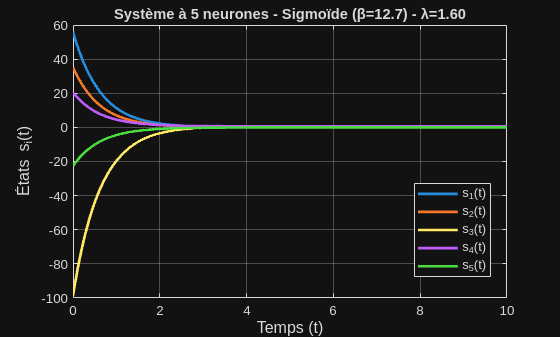

lambda =1.6;
beta =12.7;
w_mode = 4;
w_off =9.6;
B_mode = 2;
B_off =4.1;
S_mode = 2;
S_off =16.4;
phi_choice = 2;

% Génération de la matrice W selon le mode choisi
W_mat = generate_W_matrix(n, w_mode, w_diag, w_off, w_scale);

% Génération de B selon le mode choisi
B_vec = generate_B(n, B_mode, B_off, B_scale);

% Génération de S selon le mode choisi
s0_vec = generate_s0(n, S_mode, S_off, S_scale);

% Tracé
tracer_graph2(n, lambda, beta, phi_choice, s0_vec, B_vec, W_mat);

disp(B_vec)

  -49.0420  -55.1920   33.5665   68.8784  -31.1075



disp(W_mat)

     2     0     0     0     0
     0     2     0     0     0
     0     0     2     0     0
     0     0     0     2     0
     0     0     0     0     2



#### Q3/ Système à n neurones - On veut trouver numériquement W ∗ qui minimise H(W ) sur Mn (R)

- Calcul des dérivées partielles

n = 10;
T = 5;


phit = @(x) 1./( 1+ exp(-x(1:length(x))));
dphi = @(x) exp(-x) / (1 + exp(-x) )^2;


B = ones(n,1) + (1:n)'/(n-1);
W0 = eye(n,n);
Wstar = zeros(n,n);


% On a supposé lambda = 1
xi = @(s) -s+phit(Wstar*s+B);


% y est la solution de l'EDO y' = xi(y). On l'estime avec la méthode
% d'Euler explicite
h = 0.01;
Npas = T/h;
tspan = (0:Npas)*h;


y = zeros(n,Npas+1); % 1 ligne par composantes, 1 colonne par instant t = j*h
y(:,1) = 0.25* (ones(n,1) - 0.5* (1:n)'/ (n-1) ) ;


for j=1:Npas
   y(:,j+1) = y(:,j) + h*xi(y(:,j));
end


if(0)
   for k=1:length(y(:,1))
       plot(tspan,y(k,:));
       hold on
   end
   hold off
end

% calcul des dérivées partielles de H par rapport à w_ij à W donnée


function [I] = dH(i,j,W,y,B,dphi,phit,xi)
   N = length(y);
   h = 0.01;
   modele = @(i,j,u) 2*y(j,u)*dphi( W(i,:)*y(:,u) + B(i) )*sum( phit(W*y(:,u) +B) -y(:,u) - xi(y(:,u)) );
  
   I = 0;
   for k=1:N
       I = I + h*modele(i,j,k); % k correspond au rang de l'instant d'évaluation, qui vaut k*h
   end
end


res11 = dH(1,1,W0,y,B,dphi,phit,xi)

res11 = 0.6240

res12 = dH(1,1,Wstar,y,B,dphi,phit,xi)

res12 = 0

res13 = dH(4,5,Wstar,y,B,dphi,phit,xi)

res13 = 0

        2. Utilisation d'une descente de gradient sur la fonction H

Niter = 50;
U = W0; % pas possible de faire U de taille Niter*n*n car pb pour multiplier ensuite
function [I] = H(W,y,B,phit,xi)
   N = length(y);
   h = 0.01;
   modele = @(u) (norm( phit( W*y(:,u) + B ) -y(:,u) -xi(y(:,u))  , 2))^2;
  
   I = 0;
   for k=1:N
       I = I + h.*modele(k); % k correspond au rang de l'instant d'évaluation, qui vaut k*h
   end
end


res = H(Wstar,y,B,phit,xi);

pas = 0.005; % choix du pas à revoir


for k=1:Niter
   for i=1:n
       for j=1:n
           U(i,j) = U(i,j)-pas*dH(i,j,U,y,B,dphi,phit,xi);
       end
   end
end


res2 = U

res2 =     0.8871   -0.1154   -0.1178   -0.1200   -0.1221   -0.1240   -0.1257   -0.1273   -0.1288   -0.1301
   -0.1011    0.8966   -0.1055   -0.1075   -0.1094   -0.1111   -0.1126   -0.1141   -0.1154   -0.1166
   -0.0901   -0.0921    0.9060   -0.0958   -0.0975   -0.0990   -0.1004   -0.1017   -0.1028   -0.1039
   -0.0800   -0.0818   -0.0835    0.9149   -0.0865   -0.0879   -0.0891   -0.0902   -0.0913   -0.0922
   -0.0709   -0.0725   -0.0740   -0.0754    0.9233   -0.0779   -0.0789   -0.0799   -0.0809   -0.0817
   -0.0628   -0.0642   -0.0655   -0.0667   -0.0679    0.9311   -0.0699   -0.0707   -0.0715   -0.0723
   -0.0556   -0.0568   -0.0580   -0.0590   -0.0600   -0.0610    0.9382   -0.0626   -0.0633   -0.0639
   -0.0492   -0.0503   -0.0513   -0.0523   -0.0531   -0.0539   -0.0547    0.9446   -0.0560   -0.0565
   -0.0436   -0.0445   -0.0454   -0.0463   -0.0470   -0.0477   -0.0484   -0.0490    0.9505   -0.0500
   -0.0386   -0.0395   -0.0403   -0.0410   -0.0417   -0.0423   -0.0429   -0.0434   -

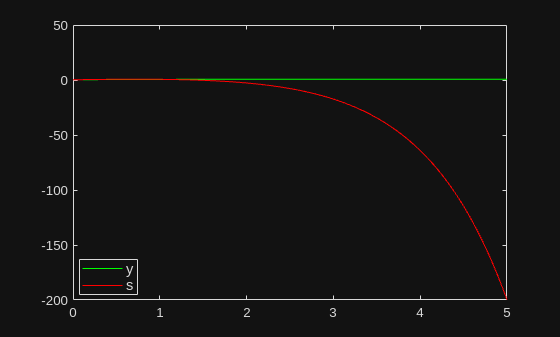

h = 0.01;
Npas = T/h;
tspan = (0:Npas)*h;


s = zeros(n,Npas+1); % 1 ligne par composante, 1 colonne par instant t = j*h
s(:,1) = 0.25* (ones(n,1) - 0.5* (1:n)'/ (n-1) ) ;


for k=1:Npas
   s(:,k+1) = s(:,k) + h.* (U*s(:,k) + B);
end


if (1)
   plot(tspan,y(1,:),'g');
   hold on
   plot(tspan,s(1,:),'r');
   hold off
   legend('y','s', 'Location', 'best', 'FontSize', 11);
end

eval_quali = norm(y-s,2)

eval_quali = 2.7279e+03

R = (9 - 80/n)*ones(n,1) - floor( (1:n)'-(n/2)*ones(n,1) )/n;


C = -2*eye(n,n) + diag(ones(n-1,1),1) + diag(ones(n-1,1),-1);
xi = @(s) C*s + R - 0.5*sum(s)*y;

####     III. Prise en compte des incertitudes

#### Q4/ Propagation des incertitudes

- Hypothèse: les données initiales du système sont distribuées selon des lois normales indépendantes

%code

        2. Incertitude sur le calcul

%code

        3. Variabilité ur les données d'entrée

%code

#### **Q5/ **

%code